## **Feature Selection Demo using Matlab - **PIMA Indians Diabetes Dataset

In this tutorial, I will use the "PIMA Indians Diabetes" dataset, where all patients are females at least 21 years old of Pima Indian heritage.

The classification task is to predict whether an individual has diabetes from the following features:

* Pregnancies: Number of times pregnant

* Glucose: Plasma glucose concentration a 2 hours in an oral glucose tolerance test

* BloodPressure: Diastolic blood pressure (mm Hg)

* SkinThickness: Triceps skin fold thickness (mm)

* Insulin: 2-Hour serum insulin (mu U/ml)

* BMI: Body mass index (weight in kg/(height in m)^2)

* DiabetesPedigreeFunction: Diabetes pedigree function

* Age: (years)

* Outcome (Has Diabetes): Class variable (0 or 1)

datafile=bmes.downloadurl('https://raw.githubusercontent.com/jbrownlee/Datasets/master/pima-indians-diabetes.data.csv');
%datafile does not contain a header row, so we are hardcoding the column
%names here:
names={'numpregnancies', 'glucose', 'diastolic', 'tricepskin', 'insulin', 'bmi', 'pedigree', 'age', 'hasdiabetes'};

t=readtable(datafile);
t.Properties.VariableNames=names;
t(1:5,:) % show a few rows as examples

ans = 5×9 table
    numpregnancies    glucose    diastolic    tricepskin    insulin    bmi     pedigree    age    hasdiabetes
    ______________    _______    _________    __________    _______    ____    ________    ___    ___________

          6             148         72            35            0      33.6     0.627      50          1     
          1              85         66            29            0      26.6     0.351      31          0     
          8             183         64             0            0      23.3     0.672      32          1     
          1              89         66            23           94      28.1     0.167      21          0     
          0      

t(end,:)=[]; %throwing away one sample, to demonstrate unequal # of samples in k-fold

% Assuming the last column represents the target class ('hasdiabetes')
X=t{:,1:end-1};
T=t{:,end};
size(X)

ans =    767     8


totalnumberofsamples = size(T,1)

totalnumberofsamples = 767

### Evaluation Function for Wrapper Method

% Previously, we were doing cross-validation manually. Enclosing train &
% testing of a model in a function will simplify that.
% Let's first manually do train & test:

Icross = crossvalind('kfold',size(X,1),4);
Itest = Icross == 1;
%%
Xtest = X(Itest, :);
Ttest = T(Itest);
Xtrain = X(~Itest, :);
Ttrain = T(~Itest);

%=====================================================================
% I use SVM, you can replace this with another machine language of your
% choice.
% You must use a machine learning method that is appropriate for your
% prediction problem (especially classification vs. regression).
mdl = fitcsvm(Xtrain,Ttrain,'KernelFunction','rbf');

Ytest = mdl.predict(Xtest);

% You need to use an error calculation that is approporiate for your
% prediction problem (especially classification vs. regression). Also pay
% attention to two-class vs. multi-class classification problems.
cp = classperf(Ttest, Ytest);
numberofmistakes =  cp.ErrorRate * size(Ttest, 1);
%=====================================================================

accuracy = 1-   numberofmistakes / size(Ttest,1)

accuracy = 0.6615

% I have enclosed the code above in an external function,
% diabetes_svm_evaluatefor1fold.m, so I can call that function for any X/T
% subsets.
numberofmistakes = diabetes_svm_evaluatefor1fold( Xtrain, Ttrain, Xtest, Ttest )

numberofmistakes = 65


accuracy = 1- numberofmistakes / size(Ttest,1)

accuracy = 0.6615


type diabetes_svm_evaluatefor1fold.m

function numberofmistakes=diabetes_svm_evaluatefor1fold( Xtrain, Ttrain, Xtest, Ttest)
% An evaluation function for featureselection must train using Xtrain &
% Train and test using Xtest & Ytest. Return the total error (not average
% error).
% by AhmetSacan

% I use SVM, you can replace this with another machine language of your
% choice.
% You must use a machine learning method that is appropriate for your
% prediction problem (especially classification vs. regression).
mdl = fitcsvm(Xtrain,Ttrain,'KernelFunction','rbf');

Ytest = mdl.predict(Xtest);

% You need to use an error calculation that is approporiate for your
% prediction problem (especially classification vs. regression). Also pay
% attention to two-class vs. multi-class classification problems.
cp = classperf(Ttest, Ytest);
numberofmistakes =  cp.ErrorRate * size(Ttest, 1);



**Evaluation with all features, using the objective Function**

% For comparison, let's find out the accuracy using all features, before we
% do feature selection.
cv = cvpartition(T,'Kfold',4);
% We can use the evaluation function to run crossvalidation (let matlab run
% for each fold).
testerrors = crossval(@diabetes_svm_evaluatefor1fold, X,T, 'partition',cv)

testerrors =     67
    67
    67
    67


crossvalaccuracy = 1 - sum(testerrors)/totalnumberofsamples;
fprintf('%.10f\n',crossvalaccuracy)

0.6505867014


% Below is incorrect method of calculating average accuracy:
testaccuracies = zeros(cv.NumTestSets,1);
for i=1:cv.NumTestSets
	testaccuracies(i) = 1-testerrors(i)/nnz(cv.test(i));
end
accuracyavg = mean(testaccuracies);
fprintf('%.10f\n',accuracyavg)

0.6505849149


accuracystd = std(testaccuracies)

accuracystd = 9.1350e-04

## Filter-based Feature Selection

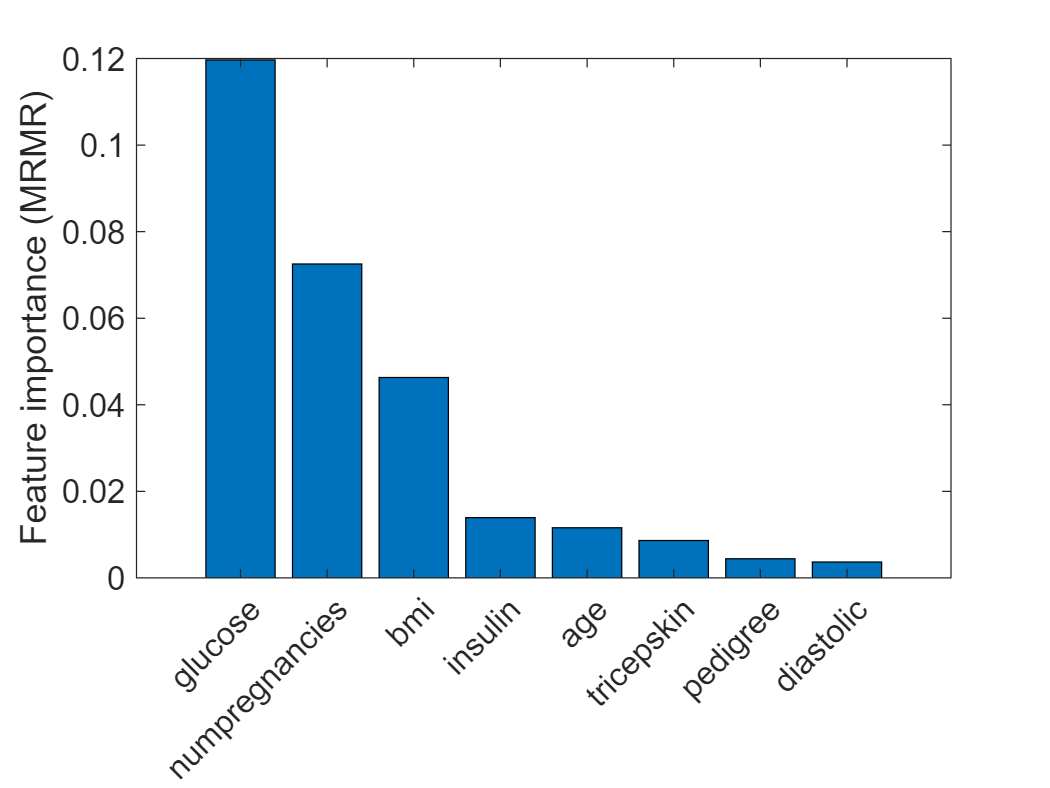

% You need to make sure you are using a criteria that is appropriate for
% classification vs. regression problems. See some filter options at:
% https://www.mathworks.com/help/stats/feature-selection.html
% You can implement other strategies using Matlab's statistics functions
% e.g., using ttest to order each feature by its p-value) or use third
% party functions (e.g., chi square feature selection available at:
% https://www.mathworks.com/matlabcentral/fileexchange/28012-chi-square-feature-analysis

%%
% Here I will use the "Minimum Redundancy Maximum Relevance (MRMR)
% Algorithm" implemented by fscmrmr(). 
[Isorted,mrmrscores] = fscmrmr(X,T);


bar(mrmrscores(Isorted));
h=gca;
h.XTickLabel=names(Isorted);
h.XTickLabelRotation=45;
ylabel('Feature importance (MRMR)') ;

%% Perform classification with the filter-based selected features
% Let's use top 3 features.
Xselected = X(:,Isorted(1:3));
totalerror=sum(crossval(@diabetes_svm_evaluatefor1fold,Xselected,T,'partition',cv));
accuracy = 1-totalerror/size(T,1)

accuracy = 0.6441

## Perform Forward Selection

opts = statset('display','iter'); % create options that ask matlab to display useful info after each iteration.
[Iselected,history] = sequentialfs(@diabetes_svm_evaluatefor1fold,X,T,'cv',cv,'options',opts,'direction','forward');

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 2, criterion value 0.297262
Step 2, added column 7, criterion value 0.284224
Final columns included:  2 7 


%%
% Ifeats are the indices of the selected features. To build your "final"
% model, you would use this variable.
Iselected

Iselected = 1×8 logical array
   0   1   0   0   0   0   1   0



%%
% history.In lists the features that were selected after each iteration.
history.In

ans = 2×8 logical array
   0   1   0   0   0   0   0   0
   0   1   0   0   0   0   1   0



%%
% history.Crit lists the scores (ie., total error returned from our
% evaluation function) of the features that were selected after each
% iteration.
history.Crit

ans =     0.2973    0.2842


crossvalerror = sum(crossval(@diabetes_svm_evaluatefor1fold, X(:,Iselected), T   , 'partition',cv)) / totalnumberofsamples

crossvalerror = 0.2842

## Forward Selection all the way

% Matlab stops selection automatically once it determines a good number of
% features have been selected. You can force matlab to select all features
% by setting 'nfeatures' option. e.g.,:
[Ifeats2,history2] = sequentialfs(@diabetes_svm_evaluatefor1fold,X,T,'cv',cv,'options',opts,'direction','forward','nfeatures',size(X,2))

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 2, criterion value 0.297262
Step 2, added column 7, criterion value 0.284224
Step 3, added column 1, criterion value 0.328553
Step 4, added column 3, criterion value 0.346806
Step 5, added column 6, criterion value 0.349413
Step 6, added column 4, criterion value 0.349413
Step 7, added column 5, criterion value 0.349413
Step 8, added column 8, criterion value 0.349413
Final columns included:  all


Ifeats2 = 1×8 logical array
   1   1   1   1   1   1   1   1


history2 = struct with fields:
      In: [8×8 logical]
    Crit: [0.2973 0.2842 0.3286 0.3468 0.3494 0.3494 0.3494 0.3494]



history2.In

ans = 8×8 logical array
   0   1   0   0   0   0   0   0
   0   1   0   0   0   0   1   0
   1   1   0   0   0   0   1   0
   1   1   1   0   0   0   1   0
   1   1   1   0   0   1   1   0
   1   1   1   1   0   1   1   0
   1   1   1   1   1   1   1   0
   1   1   1   1   1   1   1   1


history2.Crit

ans =     0.2973    0.2842    0.3286    0.3468    0.3494    0.3494    0.3494    0.3494


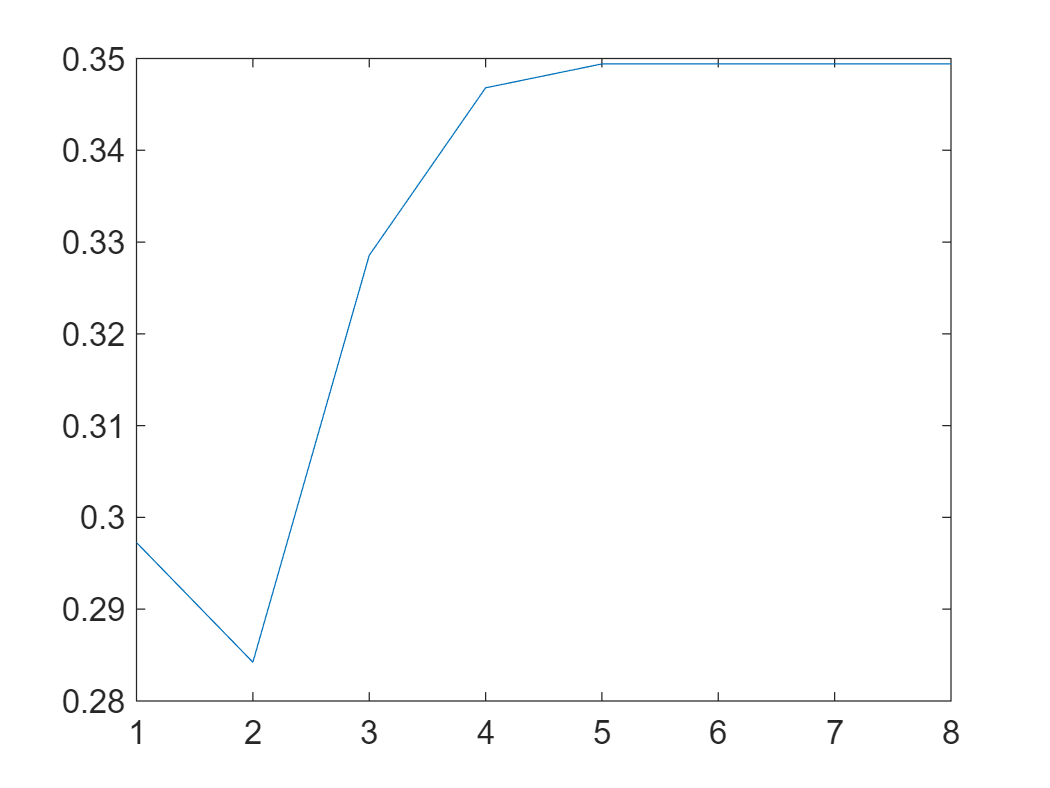


plot(history2.Crit);

xlabel('Each attributed added');
ylabel('Xvalidation error');

## Recursive Elimination

% To perform recursive elimination, just change the 'direction' option.
[Ifeats3,history3] = sequentialfs(@diabetes_svm_evaluatefor1fold,X,T,'cv',cv,'options',opts,'direction','backward')

Start backward sequential feature selection:
Initial columns included:  all
Columns that must be included:  none
Step 1, used initial columns, criterion value 0.348958
Step 2, removed column 1, criterion value 0.348958
Step 3, removed column 2, criterion value 0.348958
Step 4, removed column 3, criterion value 0.347656
Step 5, removed column 4, criterion value 0.345052
Final columns included:  5 6 7 8 


Ifeats3 = 1×8 logical array
   0   0   0   0   1   1   1   1


history3 = struct with fields:
      In: [5×8 logical]
    Crit: [0.3490 0.3490 0.3490 0.3477 0.3451]


Xselected = X(:,Ifeats3);
totalerror=sum(crossval(@diabetes_svm_evaluatefor1fold,Xselected,T,'partition',cv));
accuracy = 1-totalerror/size(T,1)

accuracy = 0.6549

**Final Model: What you will use to make actual prediction**

Xselected = X(:,Ifeats3);
mdl = fitcsvm(Xselected,T,'KernelFunction','rbf');

Y = mdl.predict(Xselected);
cp = classperf(T, Y);

%training performance: this should not be used as an indication of how well
%your model will perform on new unseen data (for that, use cross-validation
%instead).
cp.CorrectRate

ans = 0.9661